clear, clc
close all
datadir = 'G:\A_arousal_analysis\data';
% datadir = '/Volumes/zhou/A_arousal_analysis/data';
load(fullfile(datadir, 'A_arousal_connectivity_patterns.mat'))
load(fullfile(datadir, 'A_imagination_FC_dataset_new.mat'))
load(fullfile(datadir, 'fig_cols.mat'))
cols = cols./255;
cols1 = cols1./255;

## PAES and NAES responses

FC_sad1 = atanh(FC_sad1);
FC_sad1(~isfinite(FC_sad1)) = 0;
FC_sad2 = atanh(FC_sad2);
FC_sad2(~isfinite(FC_sad2)) = 0;
FC_sad3 = atanh(FC_sad3);
FC_sad3(~isfinite(FC_sad3)) = 0;

PE_sad1 = [ones(41, 1) FC_sad1(:, parcel_idx)] * b_pls;
PE_sad2 = [ones(41, 1) FC_sad2(:, parcel_idx)] * b_pls;
PE_sad3 = [ones(41, 1) FC_sad3(:, parcel_idx)] * b_pls;

FC_rumination1 = atanh(FC_rumination1);
FC_rumination1(~isfinite(FC_rumination1)) = 0;
FC_rumination2 = atanh(FC_rumination2);
FC_rumination2(~isfinite(FC_rumination2)) = 0;
FC_rumination3 = atanh(FC_rumination3);
FC_rumination3(~isfinite(FC_rumination3)) = 0;

PE_rumination1 = [ones(41, 1) FC_rumination1(:, parcel_idx)] * b_pls;
PE_rumination2 = [ones(41, 1) FC_rumination2(:, parcel_idx)] * b_pls;
PE_rumination3 = [ones(41, 1) FC_rumination3(:, parcel_idx)] * b_pls;

FC_distraction1 = atanh(FC_distraction1);
FC_distraction1(~isfinite(FC_distraction1)) = 0;
FC_distraction2 = atanh(FC_distraction2);
FC_distraction2(~isfinite(FC_distraction2)) = 0;
FC_distraction3 = atanh(FC_distraction3);
FC_distraction3(~isfinite(FC_distraction3)) = 0;

PE_distraction1 = [ones(41, 1) FC_distraction1(:, parcel_idx)] * b_pls;
PE_distraction2 = [ones(41, 1) FC_distraction2(:, parcel_idx)] * b_pls;
PE_distraction3 = [ones(41, 1) FC_distraction3(:, parcel_idx)] * b_pls;

clear FC*

PE_sad = (PE_sad1 + PE_sad2 + PE_sad3)/3;
PE_rumination = (PE_rumination1 + PE_rumination2 + PE_rumination3)/3;
PE_distraction = (PE_distraction1 + PE_distraction2 + PE_distraction3)/3;
emotion_PE = [PE_sad; PE_rumination; PE_distraction];

## ratings

see also [https://github.com/Chaogan-Yan/PaperScripts/blob/master/Chen_2020_NeuroImage/scripts/Questionnaire_stats.m](https://github.com/Chaogan-Yan/PaperScripts/blob/master/Chen_2020_NeuroImage/scripts/Questionnaire_stats.m)

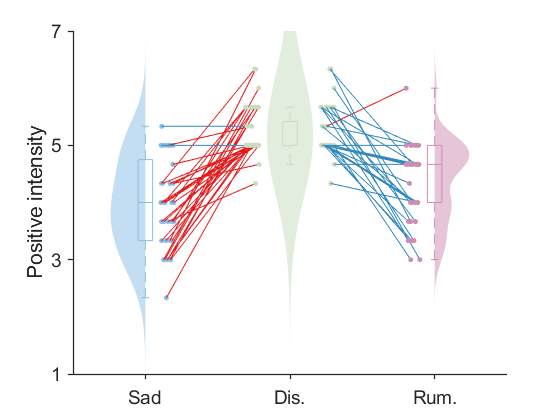

load(fullfile(datadir, 'IPCAS_QuestionnaireData.mat'))
emotion = cell2mat(EmotionScore);
emotion(:,3) = emotion(:,4);
emotion(:,4) = emotion(:,5);
emotion(:,5) = emotion(:,6);
emotion(:,6) = [];
% we focus on sad, rumination and distraction
emotion = emotion(:, 3:5);
emotion_IPCAS = emotion(:);

load(fullfile(datadir, 'PKUGE_QuestionnaireData.mat'))
emotion = cell2mat(EmotionScore);
emotion(:,3) = emotion(:,4);
emotion(:,4) = emotion(:,5);
emotion(:,5) = emotion(:,6);
emotion(:,6) = [];
emotion = emotion(:, 3:5);
emotion_PKUGE = emotion(:);

load(fullfile(datadir, 'PKUSIEMENS_QuestionnaireData.mat'))
emotion = cell2mat(EmotionScore);
emotion(:,3) = emotion(:,4);
emotion(:,4) = emotion(:,5);
emotion(:,5) = emotion(:,6);
emotion(:,6) = [];
emotion = emotion(:, 3:5);
emotion_PKUSIEMENS = emotion(:);

emotion = (emotion_IPCAS + emotion_PKUGE + emotion_PKUSIEMENS)/3;

dataConditions = {emotion(1:41), emotion(83:end), emotion(42:82)};
conditionLabels = {'Sad', 'Dis.', 'Rum.'};

righthigher = dataConditions{1} < dataConditions{2};
linecolors{1} = zeros(length(righthigher), 3);
linecolors{1}(righthigher, :) = repmat([0.8902    0.1020    0.1098], sum(righthigher), 1);
linecolors{1}(~righthigher, :) = repmat([0.1961    0.5333    0.7412], sum(~righthigher), 1);

righthigher = dataConditions{2} < dataConditions{3};
linecolors{2} = zeros(length(righthigher), 3);
linecolors{2}(righthigher, :) = repmat([0.8902    0.1020    0.1098], sum(righthigher), 1);
linecolors{2}(~righthigher, :) = repmat([0.1961    0.5333    0.7412], sum(~righthigher), 1);

plotPairedComparison(dataConditions, conditionLabels, 'dotsize', 10, 'densityscalefactor', 0.08, 'connectwidth', 0.5, 'colors', cols1([4,8,9],:), 'linecolors',linecolors);
%plotPairedComparison(dataConditions, conditionLabels, 'dotsize', 10, 'densityscalefactor', 0.1, 'connectwidth', 0.5, 'colors', cols(1:3,:));

ylabel('Positive intensity');
set(gca,'YLim', [1 7], 'ytick',1:2:7, 'tickdir', 'out');
set(gca,'FontName','Helvetica','FontSize',14, 'LineWidth', 1)


% axis square
% set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 3.5 3.5]);
% print('-dtiff', 'A_positive_rating_study3.tif', '-r400')
% 
% close all

## PAES predictions

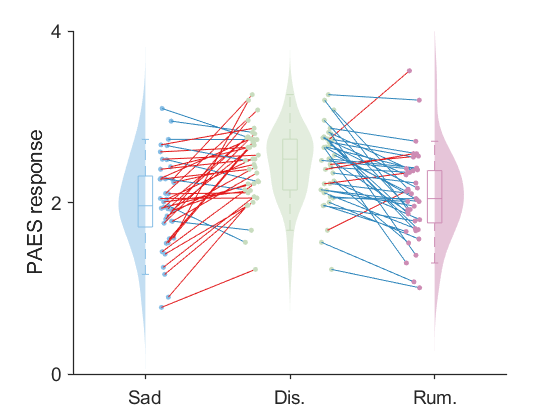

dataConditions = {emotion_PE(1:41, 1), emotion_PE(83:end, 1), emotion_PE(42:82, 1)};
conditionLabels = {'Sad', 'Dis.', 'Rum.'};

righthigher = dataConditions{1} < dataConditions{2};
linecolors{1} = zeros(length(righthigher), 3);
linecolors{1}(righthigher, :) = repmat([0.8902    0.1020    0.1098], sum(righthigher), 1);
linecolors{1}(~righthigher, :) = repmat([0.1961    0.5333    0.7412], sum(~righthigher), 1);

righthigher = dataConditions{2} < dataConditions{3};
linecolors{2} = zeros(length(righthigher), 3);
linecolors{2}(righthigher, :) = repmat([0.8902    0.1020    0.1098], sum(righthigher), 1);
linecolors{2}(~righthigher, :) = repmat([0.1961    0.5333    0.7412], sum(~righthigher), 1);

plotPairedComparison(dataConditions, conditionLabels, 'dotsize', 10, 'densityscalefactor', 0.08, 'connectwidth', 0.5, 'colors', cols1([4,8,9],:), 'linecolors',linecolors);
%plotPairedComparison(dataConditions, conditionLabels, 'dotsize', 10, 'densityscalefactor', 0.1, 'connectwidth', 0.5, 'colors', cols(1:3,:));

ylabel('PAES response');
set(gca,'YLim', [0 4], 'ytick',0:2:4, 'tickdir', 'out');
set(gca,'FontName','Helvetica','FontSize',14, 'LineWidth', 1)


% axis square
% set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 3.5 3.5]);
% print('-dtiff', 'A_PAES_response_study3.tif', '-r400')
% 
% close all

## NAES predictions

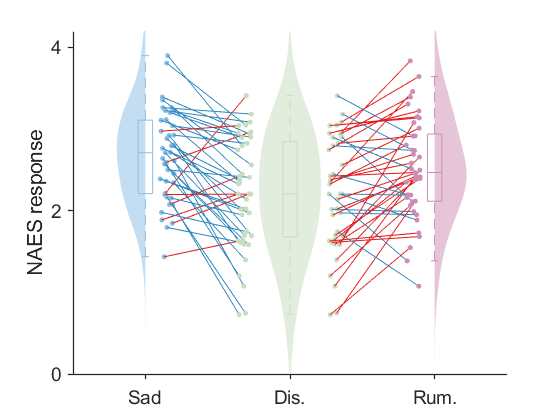

dataConditions = {emotion_PE(1:41, 2), emotion_PE(83:end, 2), emotion_PE(42:82, 2)};
conditionLabels = {'Sad', 'Dis.', 'Rum.'};

righthigher = dataConditions{1} < dataConditions{2};
linecolors{1} = zeros(length(righthigher), 3);
linecolors{1}(righthigher, :) = repmat([0.8902    0.1020    0.1098], sum(righthigher), 1);
linecolors{1}(~righthigher, :) = repmat([0.1961    0.5333    0.7412], sum(~righthigher), 1);

righthigher = dataConditions{2} < dataConditions{3};
linecolors{2} = zeros(length(righthigher), 3);
linecolors{2}(righthigher, :) = repmat([0.8902    0.1020    0.1098], sum(righthigher), 1);
linecolors{2}(~righthigher, :) = repmat([0.1961    0.5333    0.7412], sum(~righthigher), 1);

plotPairedComparison(dataConditions, conditionLabels, 'dotsize', 10, 'densityscalefactor', 0.08, 'connectwidth', 0.5, 'colors', cols1([4,8,9],:), 'linecolors',linecolors);
%plotPairedComparison(dataConditions, conditionLabels, 'dotsize', 10, 'densityscalefactor', 0.1, 'connectwidth', 0.5, 'colors', cols(1:3,:));

ylabel('NAES response');
set(gca,'YLim', [0 4.2], 'ytick',0:2:4, 'tickdir', 'out');
set(gca,'FontName','Helvetica','FontSize',14, 'LineWidth', 1)


% axis square
% set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 3.5 3.5]);
% print('-dtiff', 'A_NAES_response_study3.tif', '-r400')
% 
% close all

## rating & PAES response association

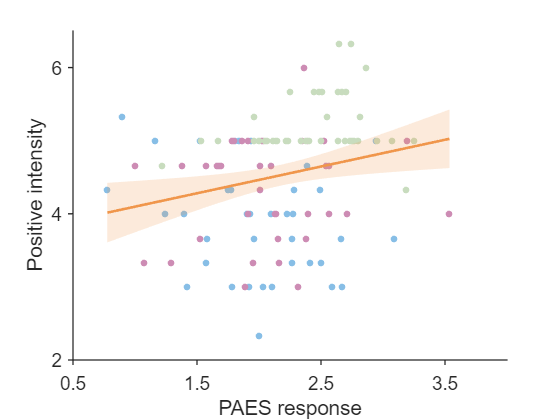

subject = repmat(1:41, 1, 3)';
tbl = table(emotion_PE(:,1), emotion, subject, 'VariableNames', {'x','y', 'subj'});
mdl = fitlme(tbl, 'y ~ x + (1|subj)');
xg = linspace(min(emotion_PE(:,1)), max(emotion_PE(:,1)), 200)';
tbl_new = table(xg, ones(length(xg), 1), 'VariableNames', {'x', 'subj'});
[yg, yCI] = predict(mdl, tbl_new, 'Alpha', 0.05, 'Conditional', false);


figure; hold on
scatter(emotion_PE(1:41,1), emotion(1:41), 25, cols1(4,:), 'filled')  
scatter(emotion_PE(42:82,1), emotion(42:82), 25, cols1(9,:), 'filled') 
scatter(emotion_PE(83:end,1), emotion(83:end), 25, cols1(8,:), 'filled') 
fill([xg; flipud(xg)], [yCI(:,1); flipud(yCI(:,2))], ...
	cols(1,:), 'FaceAlpha', 0.2, 'EdgeColor', 'none');

plot(xg, yg, 'Color', cols(1,:), 'LineWidth', 2);

xlabel('PAES response');
ylabel('Positive intensity');
set(gca,'XLim', [0.5 4], 'xtick',0.5:1:3.5,'YLim', [2 6.5], 'ytick',2:2:6, 'tickdir', 'out', 'linewidth', 1);
set(gca,'FontName','Helvetica','FontSize',14)


% axis square
% set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 3.5 3.3]);
% print('-dtiff', 'A_PAES_rating_study3.tif', '-r400')
% 
% close all

## rating & NAES response association

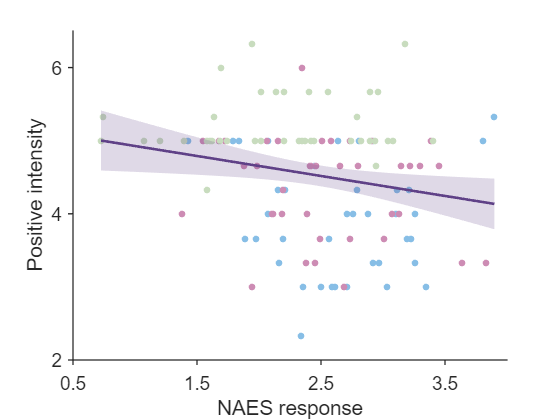

subject = repmat(1:41, 1, 3)';
tbl = table(emotion_PE(:,2), emotion, subject, 'VariableNames', {'x','y', 'subj'});
mdl = fitlme(tbl, 'y ~ x + (1|subj)');
xg = linspace(min(emotion_PE(:,2)), max(emotion_PE(:,2)), 200)';
tbl_new = table(xg, ones(length(xg), 1), 'VariableNames', {'x', 'subj'});
[yg, yCI] = predict(mdl, tbl_new, 'Alpha', 0.05, 'Conditional', false);

figure; hold on
scatter(emotion_PE(1:41,2), emotion(1:41), 25, cols1(4,:), 'filled')  
scatter(emotion_PE(42:82,2), emotion(42:82), 25, cols1(9,:), 'filled') 
scatter(emotion_PE(83:end,2), emotion(83:end), 25, cols1(8,:), 'filled') 

fill([xg; flipud(xg)], [yCI(:,1); flipud(yCI(:,2))], ...
	cols(3,:), 'FaceAlpha', 0.2, 'EdgeColor', 'none');

plot(xg, yg, 'Color', cols(3,:), 'LineWidth', 2);

xlabel('NAES response');
ylabel('Positive intensity');
set(gca,'XLim', [0.5 4], 'xtick',0.5:1:3.5,'YLim', [2 6.5], 'ytick',2:2:6, 'tickdir', 'out', 'linewidth', 1);
set(gca,'FontName','Helvetica','FontSize',14)


% axis square
% set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 3.5 3.3]);
% print('-dtiff', 'A_NAES_rating_study3.tif', '-r400')
% 
% close all